## Homework

% Problem 0 

load('Homework3.mat');

%Problem 1 

x = score1;
y = score2;

% Try to fit the model
options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...      
    'TolFun',1e-6);

paramslb = [-inf    -inf];    % lower bound
paramsub = [inf     inf];   % upper bound

%          a    b
params0 = [1.0    0];

% Try to fit the nonlinear parametric model
modelfun = @(pp, xx) pp(1)*xx + pp(2);

[params, resnorm, residual, exitflag, output] = lsqcurvefit(modelfun,params0,x,y, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3          350877                      2.58e+05
     1          6          130410             10       2.23e+03      
     2          9         57017.9             20       1.44e+03      
     3         12         3475.35        37.0566       0.000176      
     4         15         3475.35    1.66373e-07       2.97e-05      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<

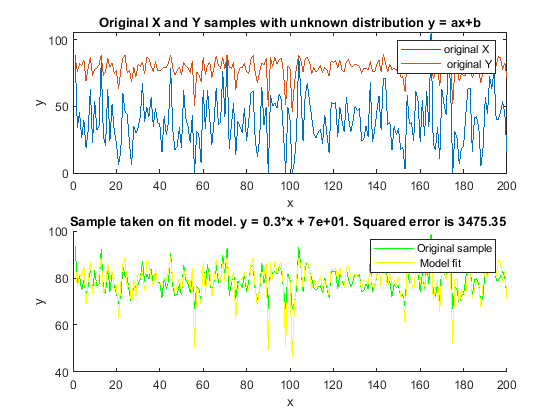

% Take a sample on predicted params
y_pred = modelfun(params,x);

% Plot data
% visualize data to take a brief look on how the data looks
figure;
subplot(2,1,1);
a = plot([score1 score2]);
xlabel('x');ylabel('y');
title('Original X and Y samples with unknown distribution y = ax+b');
legend(a,'original X', ' original Y');

% Visualize sample on predicted parameters
subplot(2,1,2);
hold on;
a = plot(y_pred,'g');
b = plot(y,'y');
xlabel('x');ylabel('y');
title(sprintf('Sample taken on fit model. y = %.g*x + %.g. Squared error is %g ',params(1), params(2), resnorm))
legend([a b], 'Original sample',' Model fit')

%Problem 2.
% The same as the problem 1, but model is (y = ax2 + bx + c)

x = score1;
y = score2;

% Try to fit the model
options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...      
    'TolFun',1e-6);

paramslb = [-inf    -inf  -inf];    % lower bound
paramsub = [inf     inf inf];   % upper bound

%          a    b   c
params0 = [1.0    0     0];

% Try to fit the nonlinear parametric model
modelfun = @(pp, xx) pp(1)*xx.^2 + pp(2)*xx + pp(3);

[params, resnorm, residual, exitflag, output] = lsqcurvefit(modelfun,params0,x,y, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     1.29939e+09                      1.33e+09
     1          8          350970             10       1.12e+05      
     2         12         78455.3             20       6.16e+06      
     3         16         2343.84         30.569         0.0264      
     4         20         2343.84     8.6785e-08       4.82e-06      

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<

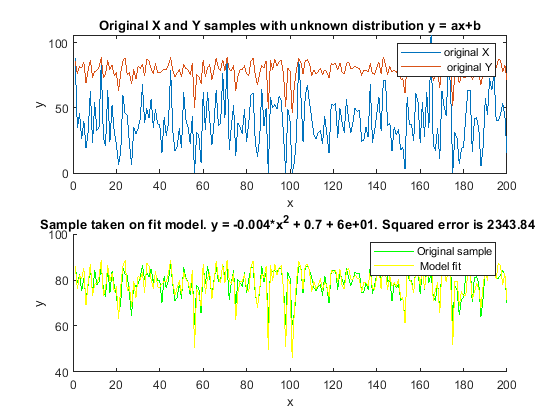

% Take a sample on predicted params
y_pred = modelfun(params,x);

% Plot data
% visualize data to take a brief look on how the data looks
figure;
subplot(2,1,1);
a = plot([score1 score2]);
xlabel('x');ylabel('y');
title('Original X and Y samples with unknown distribution y = ax+b');
legend(a,'original X', ' original Y');

% Visualize sample on predicted parameters
subplot(2,1,2);
hold on;
a = plot(y_pred,'g');
b = plot(y,'y');
xlabel('x');ylabel('y');
title(sprintf('Sample taken on fit model. y = %.g*x^2 + %.g + %.g. Squared error is %g ',params(1), params(2), params(3), resnorm))
legend([a b], 'Original sample',' Model fit')

% Problem 3

% Same as Problem 1 and Problem , but model is y = ax^n + b.
% Use two diffirent initial seed

% Let start from a = 1, n = 1, b = 0
% Then do the same for a = 10, n = 7, b = 100


x = score1;
y = score2;

% Try to fit the model
options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...      
    'TolFun',1e-6);

paramslb = [-inf    -inf    -inf];    % lower bound
paramsub = [ inf     inf     inf];   % upper bound

%          a    n   c
params01 = [1.0    1.0     0];
%          a    n   c
params02 = [10.0    7.0     100];

% Try to fit the nonlinear parametric model
modelfun = @(pp, xx) pp(1)*x.^pp(2) + pp(3);


% Fit model for the first initial seed case
[params1, resnorm1, residual, exitflag, output] = lsqcurvefit(modelfun,params01,x,y, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          350877                      9.33e+05
     1          8          142784             10       1.96e+05      
     2         12           50428             20       7.63e+04      
     3         16         3081.33        24.6048       7.46e+03      
     4         20         3081.33        5.49811       7.46e+03      
     5         24          2952.7        1.37453       2.94e+04      
     6         28         2328.91       0.343632            321      
     7         32         2138.52       0.687264       4.79e+03      
     8         36         1953.21        1.37453       1.55e+04      
     9         40         1698.71        1.37453       1.12e+04      
    10         44         1698.71        3.19799       1.12e+04      
    11         48          1576.4       0.687264       2.19e+03      
    12         52         1518.7


% Do the same for the second initial seed case
% Fit model for the first initial seed
[params2, resnorm2, residual, exitflag, output] = lsqcurvefit(modelfun,params02,x,y, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     3.10275e+30                      1.43e+31
     1          8     2.13314e+16             10       2.57e+22      
     2         12         98712.3    8.29157e-07       3.74e+11      

Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<

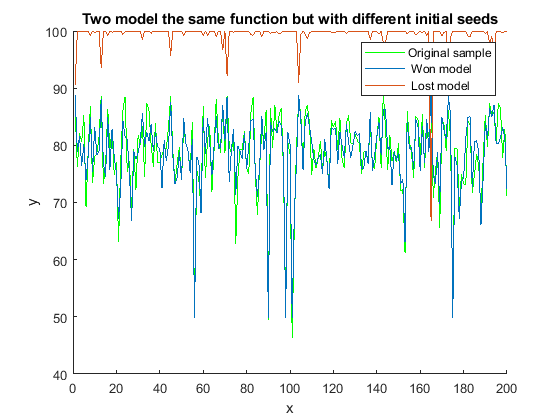


% Choose the model with the least squarred root error
won_model = [];
lost_model = [];

if(resnorm1 <= resnorm2)
    won_model = params1;
    lost_model = params2;
else
    won_model = params2;
    lost_model = params1;
end


% Visualize the won and the lost model
figure;
hold on;
a = plot(y,'g');
b = plot(modelfun(won_model,x));
c = plot(modelfun(lost_model,x),'-');
xlabel('x');ylabel('y');
title('Two model the same function but with different initial seeds')
legend([a b c ], 'Original sample',' Won model', ' Lost model')



disp(sprintf('Won model: y = %.g*x^%.g + %.g. ',won_model(1), won_model(2), won_model(3)))

Won model: y = 1e+01*x^0.3 + 5e+01. 


disp(sprintf('Lost model: y = %.g*x^%.g + %.g. ',lost_model(1), lost_model(2), lost_model(3)))

Lost model: y = -2e-13*x^7 + 1e+02. 


% Problem 4 

% Function is y = ax + b
% Derivative function is y' = a

% https://ferdidolot.wordpress.com/2015/11/17/computing-gradient-descent-using-matlab/


a = 0.0001;
iters = 1000;
x_local = score1;
y_local = score2;
theta = [0  0];

gradientDescent(x_local, y_local, theta, a, iters )

%x_local = %


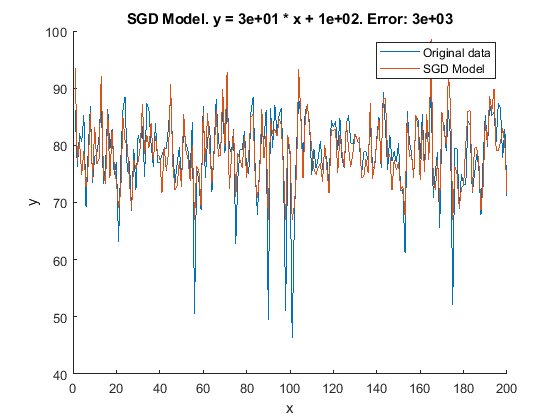


x = score1;
y = score2;

% Do you want feature normalization?

normalization = true;

% Applying mean normalization to our dataset

if (normalization)

    maxX = max(x);
    minX = min(x);
    x = (x - maxX) / (maxX - minX);

end

% Adding a column of ones to the beginning of the 'x' matrix

X = [x.^1 x.^0];


% Running gradient descent on the data

% 'x' is our input matrix
% 'y' is our output matrix
% 'parameters' is a matrix containing our initial theta and slope

parameters = [0; 0];

learningRate = abs(median(x))./sqrt(length(x));
repetition = 10000;

[parameters, costHistory] = gradientDescent(X, y, parameters, learningRate, repetition);


model_y = X * parameters;

% Final error is:
error = sum((model_y - y).^2);

%Visualize model fit
figure; hold on;
p_1 = plot(y);
p_2 = plot(model_y);
title(sprintf('SGD Model. y = %.g * x + %.g. Error: %.g',parameters(1),parameters(2), error));
legend([p_1 p_2], 'Original data','SGD Model')
xlabel('x');
ylabel('y');

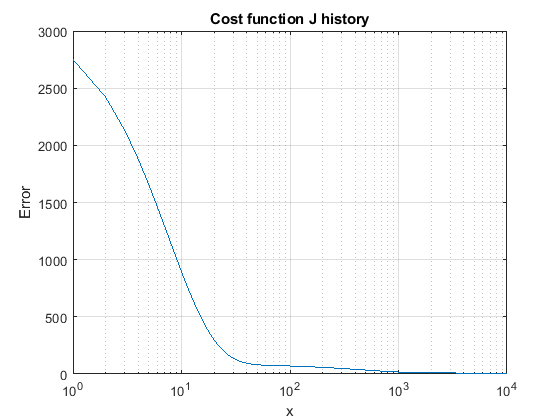


% Visualize cost history
figure;
semilogx(costHistory);
title('Cost function J history')
xlabel('x');
ylabel('Error');grid;